% Ejemplo Control del Satelite
clc;clear all;close all;
b=0.01;
J=0.5;

A=[0 1;0 -b/J];
B=[0;1/J];
C=[1 0];
D=0;

%% 1er paso LQR
Q=diag([1000 1])

Q =         1000           0
           0           1


R=0.1;
K=lqr(A,B,Q,R)

K =   100.0000   10.4781


Kr=inv(-(C-D*K)*(A-B*K)^-1*B+D)

Kr = 100.0000


%% 2do Paso LQG
Gw=[0;1/J];
Qw=0.001;
Vv=0.0001;
L=lqe(A,Gw,C,Qw,Vv)

L =     3.5366
    6.2538



%%Cierras Lazo
ACL=[A -B*K;L*C A-B*K-L*C]

ACL =          0    1.0000         0         0
         0   -0.0200 -200.0000  -20.9562
    3.5366         0   -3.5366    1.0000
    6.2538         0 -206.2538  -20.9762


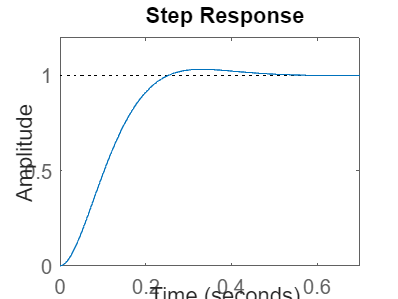

BCL=[B*Kr;B*Kr];
CCL=[C -D*K];
DCL=[D*Kr];

GCL=ss(ACL,BCL,CCL,DCL);
step(GCL)